We want to model the system using Euler-Lagrange modelling. We have two degrees of freedom $\theta_1$ and $\theta_2$.

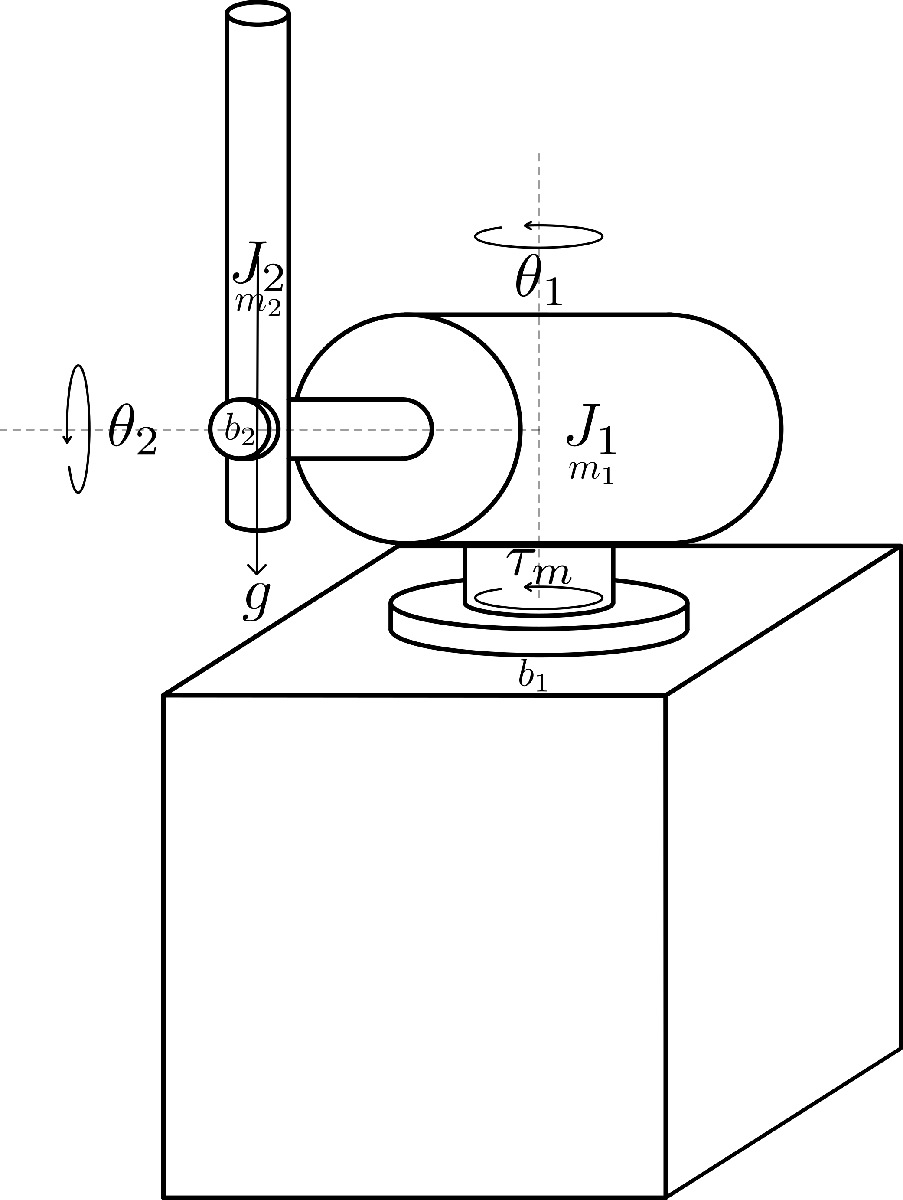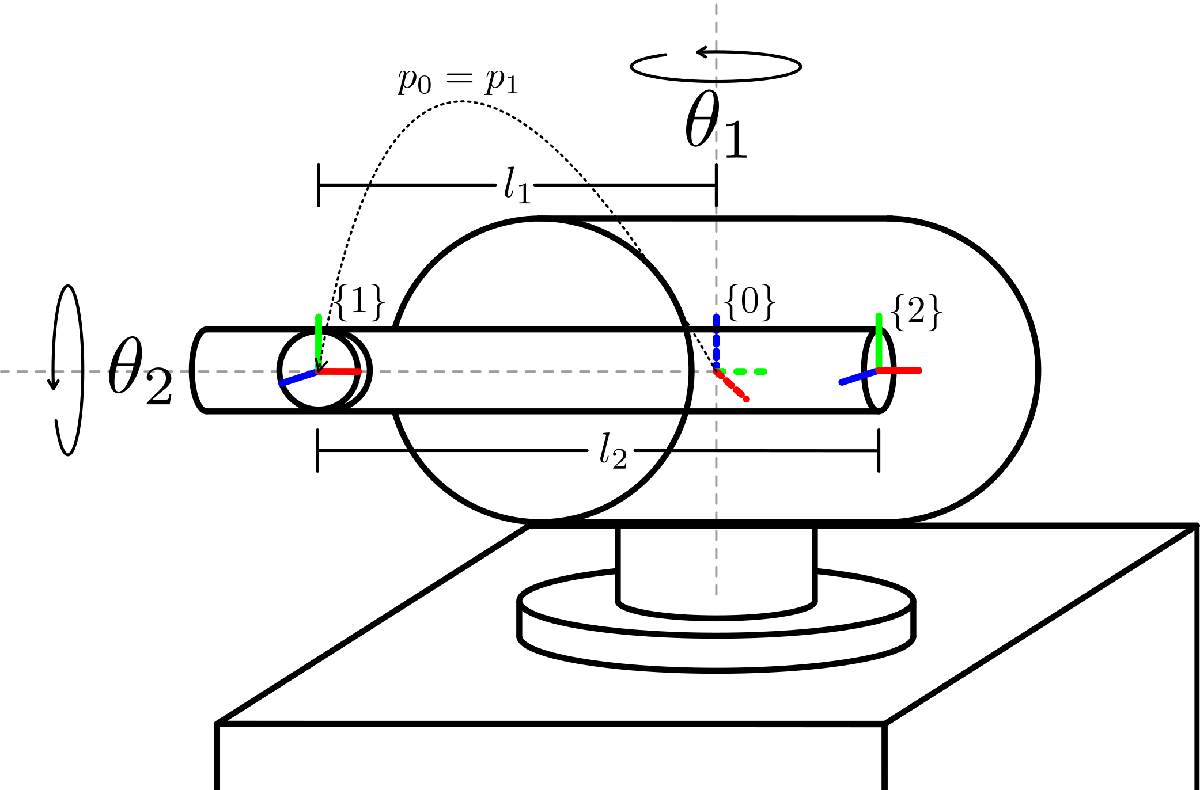

clc; clear; close all;

syms theta_1 theta_2 dtheta_1 dtheta_2 ddtheta_1 ddtheta_2 real
syms m_1 m_2 l_1 l_2 J_1 J_2 real
%syms lc1 lc2 real
syms g real
syms b_1 b_2 tau_m real

syms detB

lc1 = l_1/2;
lc2 = l_2/2;

q = [theta_1; theta_2];
dq = [dtheta_1; dtheta_2];
ddq = [ddtheta_1; ddtheta_2];

% Measurements from real life and data sheet
l_0_1 = 84.5*10^(-3);         % [m] Length from frame 0 to 1
l_1_2 = 120*10^(-3);          % [m] Length from frame 1 to 2

l_encoder = 51.9*10^(-3);     % [m] Length of encoder module
l_arm = 85*10^(-3);           % [m] Length of encoder arm (end to end)
l_p = 129*10^(-3);            % [m] Length of pendulum (end to end)

r_encoder = (27.9/2)*10^(-3); % [m] Radius of encoder module
r_arm = (6.3/2)*10^(-3);      % [m] Radius of encoder arm
r_p = (9.5/2)*10^(-3);        % [m] Radius of pendulum

m_r = 0.095;                  % [kg] Mass of encoder and arm
m_p = 0.024;                  % [kg] Mass of pendulum


Moment of inertia for a cylinder with axis of rotation perpendicular to length and touching one end of the rod


$$I_{\textrm{end}} =\frac{1}{3}M\cdot L^2 +\frac{1}{4}M\cdot R^2$$


Moment of inertia for a cylinder with axis of rotation perpendicular to length and touching middle of the rod


$$I_{\textrm{middle}} =\frac{1}{12}M\cdot L^2 +\frac{1}{4}M\cdot R^2$$


% Calculated intertia
%J_r = 1/12 * m_r * (l_encoder + l_arm)^2 + 1/4 * m_r * (r_encoder + r_arm)^2; % [kg*m^2]
J_r = 1/3 * m_r * (l_encoder + l_arm)^2 + 1/4 * m_r * (r_encoder + r_arm)^2;
J_p = 1/3 * m_p * l_p^2 + 1/4 * m_p * r_p^2; % [kg*m^2]

% Estimated friction
b_r = 0.1; % The friction for both the rotary encoder and pendulum is so low, it estimated to 0
b_p = 0.1;

% Gravity
gravity = 9.82; % [m/s^2]

% Motor parameters
k_m = 0.0422; % [Nm/A] Motor constant
R_m = 7.5;    % [Ohm] Terminal resistance
syms V_m real % Voltage

% Torque conversion from voltage
tau_real = (k_m / R_m) * V_m - (k_m^2 / R_m) * dtheta_1;
% Back EMF constant and torque constant may be different, but we treat them
% as the same.


% matlabFunction(var, 'file', 'fileName')
% latex(var)

The following is from lecture 12 of Modellering

% theta_1 *0* degrees is defined to be the motors middle-point
% theta_2 *0* degrees is defined to be the pendulum laying horizontal left
% seen from the encoders point of view. Thus *90* degrees is standing
% straight up.

% DH parameters
alpha_0 = 0;
a_0 = 0;
d_0 = 0;

alpha_1 = 90; % angle from z_i-1 to z_i measured about x_i-1
a_1 = 0; % Offset along i x-axis
d_1 = 0; % Offset along i z-axis

alpha_2 = 0; % degrees
a_2 = l_2;
d_2 = l_1; % Since we offset along the arm, this is the translation along z_2
% And since l_1 is from the end of the encoder to the joint of the
% pendulum, we will need to divide by 2 (approximately) to go from the
% middle of the encoder (frame 1 origin) to the origin of frame 2

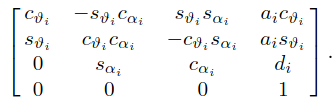

% Transformation matrix for links from DH parameters (L5 robotkinematik)
T_0_1 = [cos(theta_1) -sin(theta_1)*cosd(alpha_1)  sin(theta_1)*sind(alpha_1)  a_1*cos(theta_1);
         sin(theta_1)  cos(theta_1)*cosd(alpha_1) -cos(theta_1)*sind(alpha_1)  a_1*sin(theta_1);
                    0               sind(alpha_1)               cosd(alpha_1)               d_1;
                    0                           0                           0                 1];

T_1_2 = [cos(theta_2) -sin(theta_2)*cosd(alpha_2)  sin(theta_2)*sind(alpha_2)  a_2*cos(theta_2);
         sin(theta_2)  cos(theta_2)*cosd(alpha_2) -cos(theta_2)*sind(alpha_2)  a_2*sin(theta_2);
                    0               sind(alpha_2)               cosd(alpha_2)               d_2;
                    0                           0                           0                 1];

T_0_2 = T_0_1*T_1_2;

% Position of origo in regards to base frame
p_0 = [0;0;0];
p_0_1 = T_0_1(1:3,4);
p_0_2 = T_0_2(1:3,4)

$$p\_0\_2 = \left(\begin{array}{c} l_{1}\,\sin\left(\theta_{1}\right)+l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-l_{1}\,\cos\left(\theta_{1}\right)\\ l_{2}\,\sin\left(\theta_{2}\right) \end{array}\right)$$

% Rotation matrices
R_0_1 = T_0_1(1:3, 1:3);
R_0_2 = T_0_2(1:3, 1:3);

% Position of link center in regards to base frame
p_0_c1 = R_0_1*[0;0;lc1]+p_0_1

$$p\_0\_c1 = \left(\begin{array}{c} \frac{l_{1}\,\sin\left(\theta_{1}\right)}{2}\\ -\frac{l_{1}\,\cos\left(\theta_{1}\right)}{2}\\ 0 \end{array}\right)$$

p_0_c2 = R_0_2*[-lc2; 0; 0]+p_0_2

$$p\_0\_c2 = \left(\begin{array}{c} l_{1}\,\sin\left(\theta_{1}\right)+\frac{l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)}{2}\\ \frac{l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)}{2}-l_{1}\,\cos\left(\theta_{1}\right)\\ \frac{l_{2}\,\sin\left(\theta_{2}\right)}{2} \end{array}\right)$$


% Orientation of z-axis in regards to base frame
z_0 = [0;0;1];
z_0_1 = T_0_1(1:3, 3);
z_0_2 = T_0_2(1:3, 3);

% Jacobians for each joint (L12 modellering, and L10 robotkinematik)
J_P_1 = [cross(z_0, (p_0_c1 - p_0)) [0;0;0]]

$$J\_P\_1 = \left(\begin{array}{cc} \frac{l_{1}\,\cos\left(\theta_{1}\right)}{2} & 0\\ \frac{l_{1}\,\sin\left(\theta_{1}\right)}{2} & 0\\ 0 & 0 \end{array}\right)$$

J_P_2 = [cross(z_0, (p_0_c2 - p_0)) cross(z_0_1, (p_0_c2 - p_0_1))]

$$J\_P\_2 = \begin{array}{l} \left(\begin{array}{cc} \sigma_{1} & -\frac{l_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{2}\\ \sigma_{2} & -\frac{l_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{2}\\ 0 & \cos\left(\theta_{1}\right)\,\sigma_{2}-\sin\left(\theta_{1}\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,\cos\left(\theta_{1}\right)-\frac{l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)}{2}\\ \sigma_{2}=l_{1}\,\sin\left(\theta_{1}\right)+\frac{l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)}{2} \end{array}$$

% We will also need to find the orientational Jacobian

% To find the full expression of kinetic energy
J_O_1 = [z_0 [0;0;0]] % Only frame 0 affects the z-axis orientation of frame 1.

J_O_1 =      0     0
     0     0
     1     0


J_O_2 = [z_0 z_0_1] % Frame 0 and 1 affects the z-axis of frame 2.

$$J\_O\_2 = \left(\begin{array}{cc} 0 & \sin\left(\theta_{1}\right)\\ 0 & -\cos\left(\theta_{1}\right)\\ 1 & 0 \end{array}\right)$$

% To find the B-matrix, we will also need the inertia tensor of each link
% expressed in their own local frame.
% We can express the inertia tensor as a diagonal matrix using the intertia
% moments of each link.
% For each link, the axis of symmetry is either the z-axis (link 1)
% or the x-axis (link 2)
% From Modellering L8, latex page 13 we know, that the axis of symmetry is
% equal to I_y = I_x + I_z = 2*I_x or vice versa for a different symmetry
% axis.
% We use J as the symbol for intertia moment instead of I.
I_1_local = diag([J_1/2, J_1, J_1/2]);
I_2_local = diag([J_2, J_2/2, J_2/2]);

% Since we know, that E_kin can be expressed using both the B-matrix, and
% the Jacobians, we need to isolate the B-matrix from the equation at the
% top of this section. (Also pasted below for ease of use)
% B-matrix (L12 modellering)
B = simplify(m_1*J_P_1'*J_P_1 + m_2*J_P_2'*J_P_2 + J_O_1'*R_0_1*I_1_local*R_0_1'*J_O_1 + J_O_2'*R_0_2*I_2_local*R_0_2'*J_O_2)

$$B = \begin{array}{l} \left(\begin{array}{cc} J_{1}+\frac{3\,J_{2}}{4}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+\frac{{l_{2}}^{2}\,m_{2}}{8}-\frac{J_{2}\,\cos\left(2\,\theta_{2}\right)}{4}+\frac{{l_{2}}^{2}\,m_{2}\,\cos\left(2\,\theta_{2}\right)}{8} & \sigma_{1}\\ \sigma_{1} & \frac{m_{2}\,{l_{2}}^{2}}{4}+\frac{J_{2}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{2} \end{array}$$

E_kin_0 = simplify(1/2 * dq' * B * dq)

$$E\_kin\_0 = {\mathrm{dtheta}}_{2}\,\left(\frac{{\mathrm{dtheta}}_{2}\,\left(\frac{m_{2}\,{l_{2}}^{2}}{4}+\frac{J_{2}}{2}\right)}{2}-\frac{{\mathrm{dtheta}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{4}\right)+{\mathrm{dtheta}}_{1}\,\left(\frac{{\mathrm{dtheta}}_{1}\,\left(J_{1}+\frac{3\,J_{2}}{4}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+\frac{{l_{2}}^{2}\,m_{2}}{8}-\frac{J_{2}\,\cos\left(2\,\theta_{2}\right)}{4}+\frac{{l_{2}}^{2}\,m_{2}\,\cos\left(2\,\theta_{2}\right)}{8}\right)}{2}-\frac{{\mathrm{dtheta}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{4}\right)$$

% The g vector is how gravity affects in either direction from the base
% frame. The gravity only affects the system in the base frames z-axis
% going downards. So that is
g_direction = [0; 0; -g];
E_pot_0 = -(m_1*g_direction'*p_0_c1 + m_2*g_direction'*p_0_c2)

$$E\_pot\_0 = \frac{g\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{2}$$

## Deriviation from corialis forces

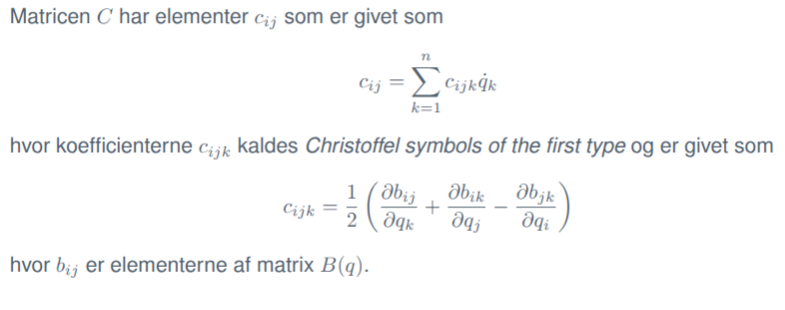

n = 2; % Number of joints
C = sym(zeros(n,n)); % Initialize C-matrix
for i = 1:n % Row of B-matrix
    for j = 1:n % Collumn of B-matrix
        for k = 1:n % Joint number
            c_ijk = 1/2 * (diff(B(i,j), q(k)) + diff(B(i,k), q(j)) - diff(B(j,k), q(i)));
            C(i,j) = C(i,j) + c_ijk * dq(k);
        end
    end
end

A Dynamical model for a robot can then be described as

We only need to calculate g(q), which is derived from E_pot as follows

g_q = [diff(E_pot_0, q(1)); diff(E_pot_0, q(2))];


% The tau vector is all generalised forces applied to the system. So that
% is input torque and friction
force_vec = [tau_m-b_1*dtheta_1; -b_2*dtheta_2]; % Only joint 1 has a torque applied to it
f_disip = [-b_1*dtheta_1; -b_2*dtheta_2]; % Disipated forces (friction)

%Thus
sys = B*ddq + C*dq + g_q == force_vec

$$sys = \begin{array}{l} \left(\begin{array}{c} {\mathrm{ddtheta}}_{1}\,\left(J_{1}+\frac{3\,J_{2}}{4}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+\frac{{l_{2}}^{2}\,m_{2}}{8}-\frac{J_{2}\,\cos\left(2\,\theta_{2}\right)}{4}+\frac{{l_{2}}^{2}\,m_{2}\,\cos\left(2\,\theta_{2}\right)}{8}\right)+{\mathrm{dtheta}}_{2}\,\left({\mathrm{dtheta}}_{1}\,\left(\sigma_{2}-\sigma_{1}\right)-\frac{{\mathrm{dtheta}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{2}\right)}{2}\right)+{\mathrm{dtheta}}_{1}\,{\mathrm{dtheta}}_{2}\,\left(\sigma_{2}-\sigma_{1}\right)-\frac{{\mathrm{ddtheta}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{2}=\tau_{m}-b_{1}\,{\mathrm{dtheta}}_{1}\\ \left(\sigma_{1}-\sigma_{2}\right)\,{{\mathrm{dtheta}}_{1}}^{2}+{\mathrm{ddtheta}}_{2}\,\left(\frac{m_{2}\,{l_{2}}^{2}}{4}+\frac{J_{2}}{2}\right)+\frac{g\,l_{2}\,m_{2}\,\cos\left(\theta_{2}\right)}{2}-\frac{{\mathrm{ddtheta}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{2}=-b_{2}\,{\mathrm{dtheta}}_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{l_{2}}^{2}\,m_{2}\,\sin\left(2\,\theta_{2}\right)}{8}\\ \sigma_{2}=\frac{J_{2}\,\sin\left(2\,\theta_{2}\right)}{4} \end{array}$$

% We can isolate ddq, to get the following
ddq_calculated = simplify(B\(f_disip - C * dq - g_q));

% Next we setup the state and system vectors
% State space vector
x = [q; dq];

% System vector
dx = [dq; ddq];

% Input vector
tau_vec = [tau_m; 0]; % Only joint 1 is affected by torque

f_x = [dq; ddq_calculated];
g_x = [0; 0; B\[1;0]] % Why are the first two values 0? does the input not affect either of the velocities?

$$g\_x = \begin{array}{l} \left(\begin{array}{c} 0\\ 0\\ \frac{8\,\left(m_{2}\,{l_{2}}^{2}+2\,J_{2}\right)}{\sigma_{1}}\\ \frac{16\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=12\,{J_{2}}^{2}-4\,{J_{2}}^{2}\,\cos\left(2\,\theta_{2}\right)+16\,J_{1}\,J_{2}+{l_{2}}^{4}\,{m_{2}}^{2}+{l_{2}}^{4}\,{m_{2}}^{2}\,\cos\left(2\,\theta_{2}\right)+8\,{l_{1}}^{2}\,{l_{2}}^{2}\,{m_{2}}^{2}+4\,J_{2}\,{l_{1}}^{2}\,m_{1}+8\,J_{1}\,{l_{2}}^{2}\,m_{2}+16\,J_{2}\,{l_{1}}^{2}\,m_{2}+8\,J_{2}\,{l_{2}}^{2}\,m_{2}-8\,{l_{1}}^{2}\,{l_{2}}^{2}\,{m_{2}}^{2}\,{\sin\left(\theta_{2}\right)}^{2}+2\,{l_{1}}^{2}\,{l_{2}}^{2}\,m_{1}\,m_{2} \end{array}$$


% For inserting in rapport, the inverse can be written as
% inv(B)= 1/det(B) * [B(2,2) -B(1,2); -B(2,1) B(1,1)]
% https://en.wikipedia.org/wiki/Invertible_matrix

ddq_test = simplify(([B(2,2) -B(1,2); -B(2,1) B(1,1)]/detB) * (f_disip - C * dq - g_q))

$$ddq\_test = \begin{array}{l} \left(\begin{array}{c} -\frac{\left(\frac{m_{2}\,{l_{2}}^{2}}{4}+\frac{J_{2}}{2}\right)\,\left(-\frac{\sigma_{3}}{2}-\frac{\sigma_{2}}{4}+\frac{\sigma_{4}}{2}+b_{1}\,{\mathrm{dtheta}}_{1}\right)}{\mathrm{detB}}-\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)\,\sigma_{1}}{2\,\mathrm{detB}}\\ -\frac{\sigma_{1}\,\left(J_{1}+\frac{3\,J_{2}}{4}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+\frac{{l_{2}}^{2}\,m_{2}}{8}-\frac{J_{2}\,\cos\left(2\,\theta_{2}\right)}{4}+\frac{{l_{2}}^{2}\,m_{2}\,\cos\left(2\,\theta_{2}\right)}{8}\right)}{\mathrm{detB}}-\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)\,\left(-\sigma_{3}-\frac{\sigma_{2}}{2}+\sigma_{4}+2\,b_{1}\,{\mathrm{dtheta}}_{1}\right)}{4\,\mathrm{detB}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{m_{2}\,\sin\left(2\,\theta_{2}\right)\,{{\mathrm{dtheta}}_{1}}^{2}\,{l_{2}}^{2}}{8}-\frac{J_{2}\,\sin\left(2\,\theta_{2}\right)\,{{\mathrm{dtheta}}_{1}}^{2}}{4}+\frac{g\,m_{2}\,\cos\left(\theta_{2}\right)\,l_{2}}{2}+b_{2}\,{\mathrm{dtheta}}_{2}\\ \sigma_{2}={\mathrm{dtheta}}_{1}\,m_{2}\,\sin\left(2\,\theta_{2}\right)\,{\mathrm{dtheta}}_{2}\,{l_{2}}^{2}\\ \sigma_{3}=l_{1}\,m_{2}\,\cos\left(\theta_{2}\right)\,{{\mathrm{dtheta}}_{2}}^{2}\,l_{2}\\ \sigma_{4}=J_{2}\,{\mathrm{dtheta}}_{1}\,\sin\left(2\,\theta_{2}\right)\,{\mathrm{dtheta}}_{2} \end{array}$$

f_test = [dq ; ddq_test]

$$f\_test = \begin{array}{l} \left(\begin{array}{c} {\mathrm{dtheta}}_{1}\\ {\mathrm{dtheta}}_{2}\\ -\frac{\left(\frac{m_{2}\,{l_{2}}^{2}}{4}+\frac{J_{2}}{2}\right)\,\left(-\frac{\sigma_{3}}{2}-\frac{\sigma_{2}}{4}+\frac{\sigma_{4}}{2}+b_{1}\,{\mathrm{dtheta}}_{1}\right)}{\mathrm{detB}}-\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)\,\sigma_{1}}{2\,\mathrm{detB}}\\ -\frac{\sigma_{1}\,\left(J_{1}+\frac{3\,J_{2}}{4}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+\frac{{l_{2}}^{2}\,m_{2}}{8}-\frac{J_{2}\,\cos\left(2\,\theta_{2}\right)}{4}+\frac{{l_{2}}^{2}\,m_{2}\,\cos\left(2\,\theta_{2}\right)}{8}\right)}{\mathrm{detB}}-\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)\,\left(-\sigma_{3}-\frac{\sigma_{2}}{2}+\sigma_{4}+2\,b_{1}\,{\mathrm{dtheta}}_{1}\right)}{4\,\mathrm{detB}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{m_{2}\,\sin\left(2\,\theta_{2}\right)\,{{\mathrm{dtheta}}_{1}}^{2}\,{l_{2}}^{2}}{8}-\frac{J_{2}\,\sin\left(2\,\theta_{2}\right)\,{{\mathrm{dtheta}}_{1}}^{2}}{4}+\frac{g\,m_{2}\,\cos\left(\theta_{2}\right)\,l_{2}}{2}+b_{2}\,{\mathrm{dtheta}}_{2}\\ \sigma_{2}={\mathrm{dtheta}}_{1}\,m_{2}\,\sin\left(2\,\theta_{2}\right)\,{\mathrm{dtheta}}_{2}\,{l_{2}}^{2}\\ \sigma_{3}=l_{1}\,m_{2}\,\cos\left(\theta_{2}\right)\,{{\mathrm{dtheta}}_{2}}^{2}\,l_{2}\\ \sigma_{4}=J_{2}\,{\mathrm{dtheta}}_{1}\,\sin\left(2\,\theta_{2}\right)\,{\mathrm{dtheta}}_{2} \end{array}$$


det(B)

$$ans = \frac{3\,{J_{2}}^{2}}{8}-\frac{{J_{2}}^{2}\,\cos\left(2\,\theta_{2}\right)}{8}+\frac{J_{1}\,J_{2}}{2}+\frac{{l_{2}}^{4}\,{m_{2}}^{2}}{32}+\frac{{l_{2}}^{4}\,{m_{2}}^{2}\,\cos\left(2\,\theta_{2}\right)}{32}+\frac{{l_{1}}^{2}\,{l_{2}}^{2}\,{m_{2}}^{2}}{4}+\frac{J_{2}\,{l_{1}}^{2}\,m_{1}}{8}+\frac{J_{1}\,{l_{2}}^{2}\,m_{2}}{4}+\frac{J_{2}\,{l_{1}}^{2}\,m_{2}}{2}+\frac{J_{2}\,{l_{2}}^{2}\,m_{2}}{4}-\frac{{l_{1}}^{2}\,{l_{2}}^{2}\,{m_{2}}^{2}\,{\sin\left(\theta_{2}\right)}^{2}}{4}+\frac{{l_{1}}^{2}\,{l_{2}}^{2}\,m_{1}\,m_{2}}{16}$$

g_test = [0; 0; ([B(2,2) -B(1,2); -B(2,1) B(1,1)]/detB)*[1;0]] 

$$g\_test = \left(\begin{array}{c} 0\\ 0\\ \frac{\frac{m_{2}\,{l_{2}}^{2}}{4}+\frac{J_{2}}{2}}{\mathrm{detB}}\\ \frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{2\,\mathrm{detB}} \end{array}\right)$$


% The state space system is then
ss_sys = simplify(f_x + g_x*tau_m) % Det er jo mega langt...

% We will need to linearize this to get the A and B vector in steady state.
% A_ss and B_ss are found by differentiating either f_x or g_x and
% evaluating at the equilibrium point (the point where the system is
% stable). The equilibrium point must relate the the state vector x and the
% input tau_m.
% The system must then be stable when:
% - theta_2 = pi/2 rad (90 degrees), as it will then be standing upright
% - dtheta_1 = dtheta_2 = 0 rad/s, as neither the motor or pendulum will
% then be moving
% - tau_m = 0, as there is then no motor input
% - theta_1 is arbitrary, as it is not relevant for the systems stability.

% We can substitute these values into f_x to check if they match.
% If it equals a 0 vector, the system is stable.
f_x_test = subs(f_x, [theta_2, dtheta_1, dtheta_2, tau_m], [pi/2, 0, 0, 0])

$$f\_x\_test = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$


% df_x/dx at equilibrium point
A_ss = [diff(f_x(1), x(1)) diff(f_x(1), x(2)) diff(f_x(1), x(3)) diff(f_x(1), x(4));
        diff(f_x(2), x(1)) diff(f_x(2), x(2)) diff(f_x(2), x(3)) diff(f_x(2), x(4));
        diff(f_x(3), x(1)) diff(f_x(3), x(2)) diff(f_x(3), x(3)) diff(f_x(3), x(4));
        diff(f_x(4), x(1)) diff(f_x(4), x(2)) diff(f_x(4), x(3)) diff(f_x(4), x(4))];

% Insert equilibrium point
A_ss = subs(A_ss, [theta_2, dtheta_1, dtheta_2, tau_m], [pi/2, 0, 0, 0])

$$A\_ss = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & \frac{4\,g\,l_{1}\,{l_{2}}^{2}\,{m_{2}}^{2}}{\sigma_{1}} & -\frac{2\,\left(2\,b_{1}\,m_{2}\,{l_{2}}^{2}+4\,J_{2}\,b_{1}\right)}{\sigma_{1}} & -\frac{8\,b_{2}\,l_{1}\,l_{2}\,m_{2}}{\sigma_{1}}\\ 0 & \frac{8\,g\,{l_{1}}^{2}\,l_{2}\,{m_{2}}^{2}+8\,J_{1}\,g\,l_{2}\,m_{2}+8\,J_{2}\,g\,l_{2}\,m_{2}+2\,g\,{l_{1}}^{2}\,l_{2}\,m_{1}\,m_{2}}{\sigma_{1}} & -\frac{8\,b_{1}\,l_{1}\,l_{2}\,m_{2}}{\sigma_{1}} & -\frac{16\,J_{1}\,b_{2}+16\,J_{2}\,b_{2}+4\,b_{2}\,{l_{1}}^{2}\,m_{1}+16\,b_{2}\,{l_{1}}^{2}\,m_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=8\,{J_{2}}^{2}+8\,J_{1}\,J_{2}+2\,J_{2}\,{l_{1}}^{2}\,m_{1}+4\,J_{1}\,{l_{2}}^{2}\,m_{2}+8\,J_{2}\,{l_{1}}^{2}\,m_{2}+4\,J_{2}\,{l_{2}}^{2}\,m_{2}+{l_{1}}^{2}\,{l_{2}}^{2}\,m_{1}\,m_{2} \end{array}$$

% We assume that the effect of the input on the system 
% is constant near the equilibrium point. 
% Thus, we simply evaluate g_x at the equilibrium point to get B_ss.
B_ss = subs(g_x, [theta_2, dtheta_1, dtheta_2, tau_m], [pi/2, 0, 0, 0])

$$B\_ss = \begin{array}{l} \left(\begin{array}{c} 0\\ 0\\ \frac{8\,\left(m_{2}\,{l_{2}}^{2}+2\,J_{2}\right)}{\sigma_{1}}\\ \frac{16\,l_{1}\,l_{2}\,m_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=16\,{J_{2}}^{2}+16\,J_{1}\,J_{2}+4\,J_{2}\,{l_{1}}^{2}\,m_{1}+8\,J_{1}\,{l_{2}}^{2}\,m_{2}+16\,J_{2}\,{l_{1}}^{2}\,m_{2}+8\,J_{2}\,{l_{2}}^{2}\,m_{2}+2\,{l_{1}}^{2}\,{l_{2}}^{2}\,m_{1}\,m_{2} \end{array}$$

We want the output y to be theta_2 (as we want to measure the angle of the pendulum)

C_ss = [0 1 0 0]; % C times x to get theta_2
D_ss = 0; % The input torque does not directly affect theta_2

sys1 = dx == A_ss * x + B_ss * tau_m

$$sys1 = \begin{array}{l} \left(\begin{array}{c} {\mathrm{dtheta}}_{1}={\mathrm{dtheta}}_{1}\\ {\mathrm{dtheta}}_{2}={\mathrm{dtheta}}_{2}\\ {\mathrm{ddtheta}}_{1}=\frac{8\,\tau_{m}\,\left(m_{2}\,{l_{2}}^{2}+2\,J_{2}\right)}{\sigma_{2}}-\frac{2\,{\mathrm{dtheta}}_{1}\,\left(2\,b_{1}\,m_{2}\,{l_{2}}^{2}+4\,J_{2}\,b_{1}\right)}{\sigma_{1}}+\frac{4\,g\,l_{1}\,{l_{2}}^{2}\,{m_{2}}^{2}\,\theta_{2}}{\sigma_{1}}-\frac{8\,b_{2}\,{\mathrm{dtheta}}_{2}\,l_{1}\,l_{2}\,m_{2}}{\sigma_{1}}\\ {\mathrm{ddtheta}}_{2}=\frac{\theta_{2}\,\left(8\,g\,{l_{1}}^{2}\,l_{2}\,{m_{2}}^{2}+8\,J_{1}\,g\,l_{2}\,m_{2}+8\,J_{2}\,g\,l_{2}\,m_{2}+2\,g\,{l_{1}}^{2}\,l_{2}\,m_{1}\,m_{2}\right)}{\sigma_{1}}-\frac{{\mathrm{dtheta}}_{2}\,\left(16\,J_{1}\,b_{2}+16\,J_{2}\,b_{2}+4\,b_{2}\,{l_{1}}^{2}\,m_{1}+16\,b_{2}\,{l_{1}}^{2}\,m_{2}\right)}{\sigma_{1}}+\frac{16\,l_{1}\,l_{2}\,m_{2}\,\tau_{m}}{\sigma_{2}}-\frac{8\,b_{1}\,{\mathrm{dtheta}}_{1}\,l_{1}\,l_{2}\,m_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=8\,{J_{2}}^{2}+8\,J_{1}\,J_{2}+2\,J_{2}\,{l_{1}}^{2}\,m_{1}+4\,J_{1}\,{l_{2}}^{2}\,m_{2}+8\,J_{2}\,{l_{1}}^{2}\,m_{2}+4\,J_{2}\,{l_{2}}^{2}\,m_{2}+{l_{1}}^{2}\,{l_{2}}^{2}\,m_{1}\,m_{2}\\ \sigma_{2}=16\,{J_{2}}^{2}+16\,J_{1}\,J_{2}+4\,J_{2}\,{l_{1}}^{2}\,m_{1}+8\,J_{1}\,{l_{2}}^{2}\,m_{2}+16\,J_{2}\,{l_{1}}^{2}\,m_{2}+8\,J_{2}\,{l_{2}}^{2}\,m_{2}+2\,{l_{1}}^{2}\,{l_{2}}^{2}\,m_{1}\,m_{2} \end{array}$$

sys_real = vpa(subs(sys1, [l_1, l_2, m_1, m_2, J_1, J_2, b_1, b_2, g, tau_m], [l_0_1, l_1_2, m_r, m_p, J_r, J_p, b_r, b_p, gravity, tau_real]), 6)

$$sys\_real = \left(\begin{array}{c} {\mathrm{dtheta}}_{1}={\mathrm{dtheta}}_{1}\\ {\mathrm{dtheta}}_{2}={\mathrm{dtheta}}_{2}\\ {\mathrm{ddtheta}}_{1}=5.7539\,V_{m}-102.504\,{\mathrm{dtheta}}_{1}-81.3109\,{\mathrm{dtheta}}_{2}+11.498\,\theta_{2}\\ {\mathrm{ddtheta}}_{2}=4.57509\,V_{m}-81.504\,{\mathrm{dtheta}}_{1}-718.112\,{\mathrm{dtheta}}_{2}+101.547\,\theta_{2} \end{array}\right)$$


y = C_ss*x + D_ss*tau_m

$$y = \theta_{2}$$

## Frequency domain model

We can now convert to the frequency domain to get the transfer function G(s).

syms s
G = simplify(C_ss*inv(s*eye(4)-A_ss)*B_ss+D_ss)

$$G = \frac{8\,l_{1}\,l_{2}\,m_{2}\,s}{8\,{J_{2}}^{2}\,s^{3}+16\,b_{1}\,b_{2}\,s+8\,J_{1}\,J_{2}\,s^{3}+16\,J_{1}\,b_{2}\,s^{2}+8\,J_{2}\,b_{1}\,s^{2}+16\,J_{2}\,b_{2}\,s^{2}-8\,b_{1}\,g\,l_{2}\,m_{2}+2\,J_{2}\,{l_{1}}^{2}\,m_{1}\,s^{3}+4\,J_{1}\,{l_{2}}^{2}\,m_{2}\,s^{3}+8\,J_{2}\,{l_{1}}^{2}\,m_{2}\,s^{3}+4\,J_{2}\,{l_{2}}^{2}\,m_{2}\,s^{3}+4\,b_{2}\,{l_{1}}^{2}\,m_{1}\,s^{2}+4\,b_{1}\,{l_{2}}^{2}\,m_{2}\,s^{2}+16\,b_{2}\,{l_{1}}^{2}\,m_{2}\,s^{2}-8\,g\,{l_{1}}^{2}\,l_{2}\,{m_{2}}^{2}\,s-8\,J_{1}\,g\,l_{2}\,m_{2}\,s-8\,J_{2}\,g\,l_{2}\,m_{2}\,s+{l_{1}}^{2}\,{l_{2}}^{2}\,m_{1}\,m_{2}\,s^{3}-2\,g\,{l_{1}}^{2}\,l_{2}\,m_{1}\,m_{2}\,s}$$

A_val = double(subs(A_ss, [l_1, l_2, m_1, m_2, J_1, J_2, b_1, b_2, g], [l_0_1, l_1_2, m_r, m_p, J_r, J_p, b_r, b_p, gravity]))

A_val =          0         0    1.0000         0
         0         0         0    1.0000
         0   11.4980 -102.2612  -81.3109
         0  101.5468  -81.3109 -718.1121


B_val = double(subs(B_ss, [l_1, l_2, m_1, m_2, J_1, J_2, b_1, b_2, g], [l_0_1, l_1_2, m_r, m_p, J_r, J_p, b_r, b_p, gravity]))

B_val = 1.0e+03 *

         0
         0
    1.0226
    0.8131


C_val = double(subs(C_ss, [l_1, l_2, m_1, m_2, J_1, J_2, b_1, b_2, g], [l_0_1, l_1_2, m_r, m_p, J_r, J_p, b_r, b_p, gravity]));

G_val = vpa(simplify(C_val*inv(s*eye(4)-A_val)*B_val+D_ss),4)

$$G\_val = \frac{4.026e+30\,s}{4.952e+27\,s^{3}+4.062e+30\,s^{2}+3.304e+32\,s-4.679e+31}$$

sys_SS = ss(A_val,B_val,C_val,D_ss)


sys_SS =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3       0    11.5  -102.3  -81.31
   x4       0   101.5  -81.31  -718.1
 
  B = 
          u1
   x1      0
   x2      0
   x3   1023
   x4  813.1
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



s_tf = tf('s')


s_tf =
 
  s
 
Continuous-time transfer function.
Model Properties


G_valued = vpa(simplify(subs(G, [l_1, l_2, m_1, m_2, J_1, J_2, b_1, b_2, g], [l_0_1, l_1_2, m_r, m_p, J_r, J_p, b_r, b_p, gravity])), 4)

$$G\_valued = \frac{5.054e+46\,s}{6.216e+43\,s^{3}+5.1e+46\,s^{2}+4.148e+48\,s-5.874e+47}$$

s_tf = tf('s'); G_ss = (5.054e+46*s_tf)/(4.308e+43*s_tf^3 +3.853e+46*s_tf^2+4.149e+48*s_tf-5.874e+47)


G_ss =
 
                      5.054e46 s
  ---------------------------------------------------
  4.308e43 s^3 + 3.853e46 s^2 + 4.149e48 s - 5.874e47
 
Continuous-time transfer function.
Model Properties


pole(G_ss)

ans =  -769.1433
 -125.3806
    0.1414


zero(G_ss)

ans = 0

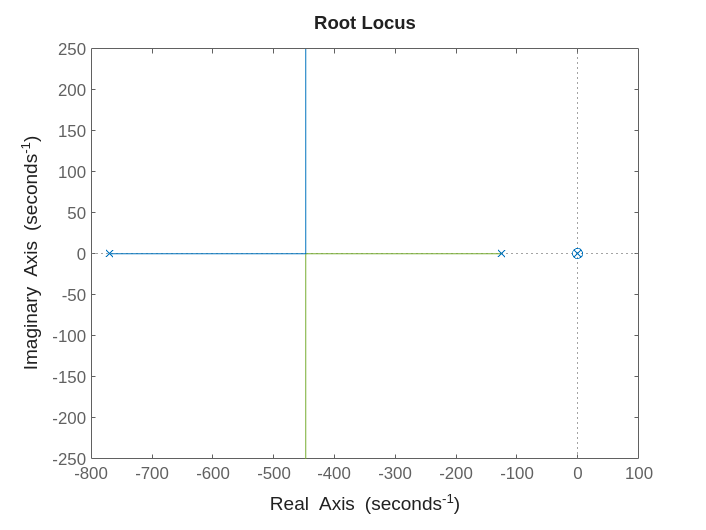

rlocus(G_ss)

[num,den] = ss2tf(sys_SS.A,sys_SS.B,sys_SS.C,sys_SS.D);
G_s = tf(num, den)


G_s =
 
    813.1 s^2 - 2.12e-08 s - 2.406e-13
  ---------------------------------------
  s^4 + 820.4 s^3 + 6.672e04 s^2 - 9449 s
 
Continuous-time transfer function.
Model Properties


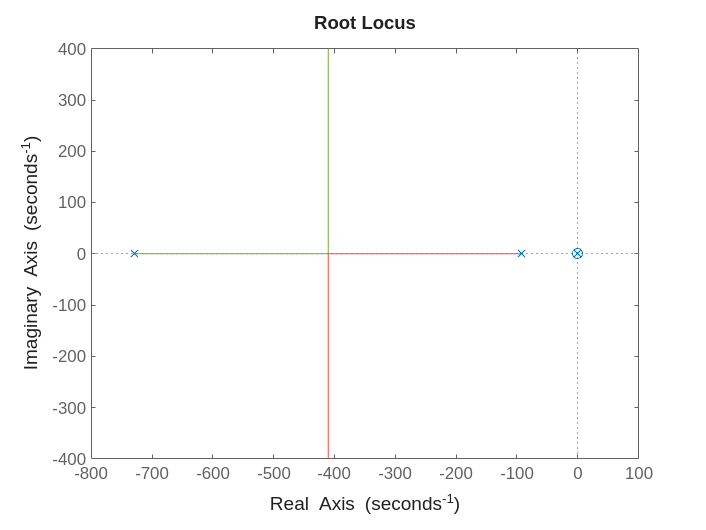


rlocus(G_s)

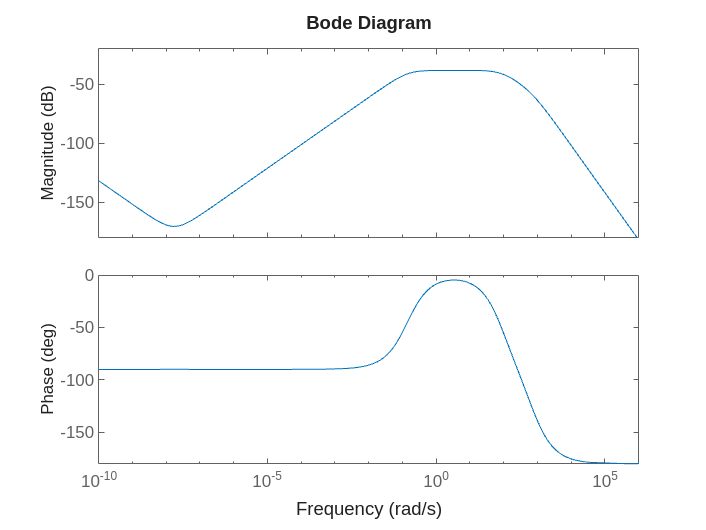

bode(G_s)

## Root locus


$$K\left(s\right)=k_P \cdot \left(1+T_d \cdot s+\frac{1}{T_i }\cdot \frac{1}{s}\right)$$


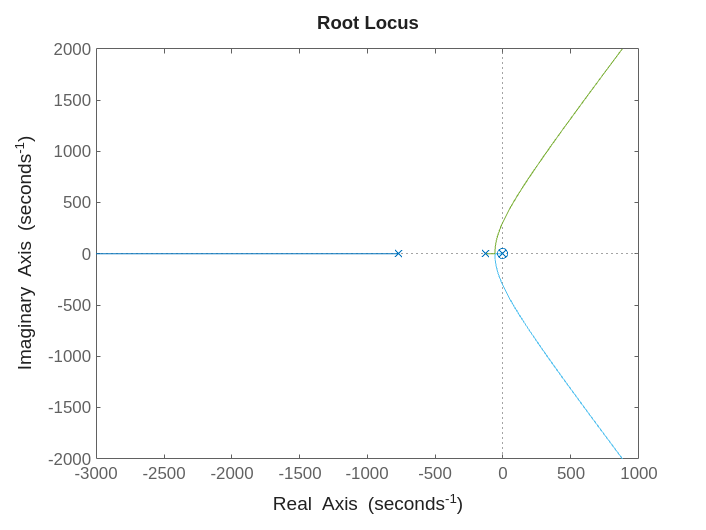

%T_i = 0.5; % Integral time constant - eliminate ss error
%T_d = T_i/4; % Derivative time constant - add damping, anticipate future error

%K_s = 1 + T_d*s_tf + 1/T_i * 1/s_tf;

% We have a pole for G_s on the right-half
K_s = 1/(s_tf-0.2);

T_s = (G_ss*K_s); % Open loop

rlocus(T_s)

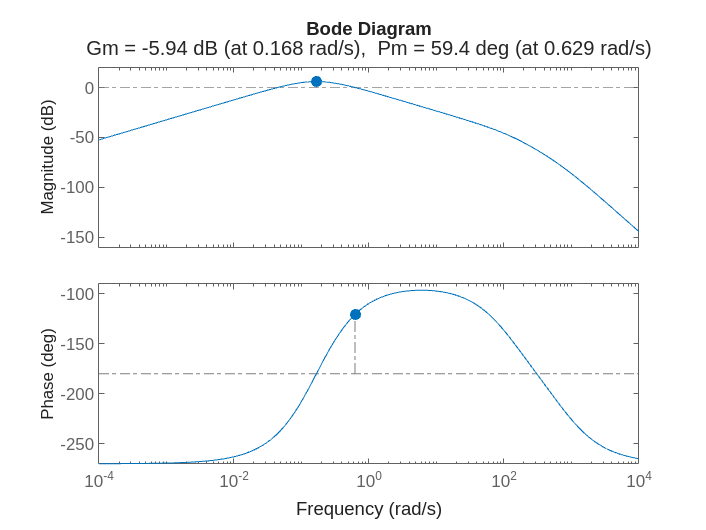

T = feedback(55.6*K_s*G_ss, 1);
margin(55.6*K_s*G_ss,{1e-4,1e4})

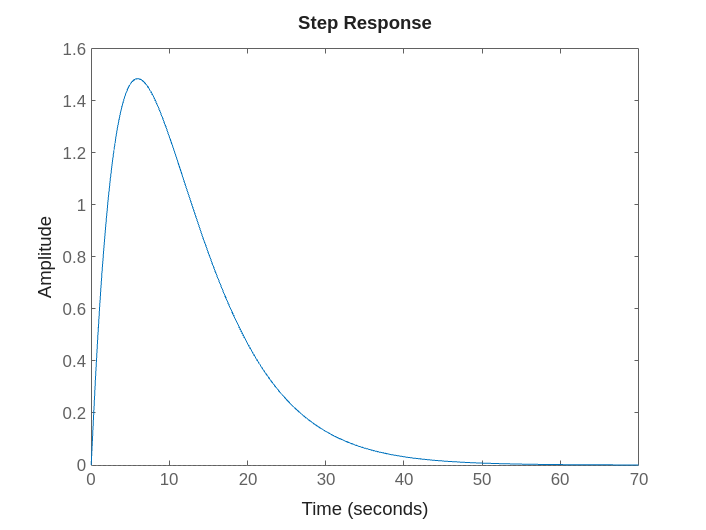

step(T)




Kp = 0.44; % From rlocus graph
w_n = 4.23; % From rlocus graph

K_sp = Kp*K_s; % Insert found gain into controller
T_sp = Kp*T_s; % Insert found gain into system

% Calculate I and D gains (for code control)
Ki = Kp/T_i;

Unrecognized function or variable 'T_i'.

Kd = Kp*T_d;

CL = feedback(T_sp,1); % Closed loop
step(CL)
% Trying to calculate setlling time
p = pole(T_sp) % Poles of system
margin(T_sp)

## Lead Compensator

% Since we have a pole which real part is greater than zero, the system is unstable.
% Thus we implement a lead compensator, to shift the pole left, to be less
% than zero.

% Plant and existing PID - Redefinitions for ease
G_s;

T_i;
T_d;
K_s;
Kp;
T_sp;
CL;

% Performance specifications
Mp    = 10;    % Overshoot (%)
Ts    = 1.5;   % Settling time (s)
alpha = 5;     % Settling band (%)


% Step 1 — Desired pole → implied phase margin requirement
% (ties the two methods together)
zeta    =  sqrt(((log(Mp)/(-pi))^2)/(1 + (log(Mp)/(-pi))^2))
sigma   = -log(alpha/100) / Ts
omega_n = sigma / zeta
omega_d = omega_n * sqrt(1 - zeta^2)